clc;
clear;
close all;

msym_tb=readcsv("1_MMFFSYMB.csv");
bs_tb=readcsv("6_MMFFBOND.csv");
ab_tb=readcsv("8_MMFFANG.csv");
sb_tb=readcsv("9_MMFFSTBN.csv");
opb_tb=readcsv("11_MMFFOOP.csv");
ti_tb=readcsv("12_MMFFTOR.csv");
vdw_tb=readcsv("13_MMFFVDW.csv");

%% 数据表格预处理_Step1_普适

bs_pro_arr=genNDarr(bs_tb,["MTYPE_I" "MTYPE_J"],["R0","KB"]);
ab_pro_arr=genNDarr(ab_tb,["MTYPE_I" "MTYPE_J" "MTYPE_K"],["THETA_0","KA_IJK"]);
[sb_fast_arr,sb_cmpl_arr]=genNDarr_cmpl(sb_tb,["MTYPE_I" "MTYPE_J" "MTYPE_K"],["KBA_IJK","KBA_KJI"]);
[opb_fast_arr,opb_cmpl_arr]=genNDarr_cmpl(opb_tb,["MTYPE_I" "MTYPE_J" "MTYPE_K" "MTYPE_L"],"KOOP","Yes");
[ti_fast_arr,ti_cmpl_arr]=genNDarr_cmpl(ti_tb,["MTYPE_I" "MTYPE_J" "MTYPE_K" "MTYPE_L"],["V1","V2","V3"],"No");
%vdw_pro_arr=genNDarr(vdw_tb,"MTYPE",["ALPHA_I","N_I","A_I","G_I"])


function cmpl_arr=short2cmpl(short_arr)
[isize,jsize]=size(short_arr);
dmax=max(short_arr,[],"all");
cmpl_arr=zeros(isize,dmax);
for i=1:isize
    for j=1:jsize
        mtype=short_arr(i,j);
        if mtype~=0
            cmpl_arr(i,mtype)=j;
        end
    end
end
end
function [arr_nd,cmpl_arr]=genNDarr_cmpl(tb,idname,dimname,is_jl_solid)

dimsize=size(dimname,2);
idsize=size(idname,2);
tbsize=size(tb,1);
arr=tb{:,[idname dimname]};
mshort=cell(idsize,1);
issize=zeros(1,idsize);
for i=1:idsize
    m=sort(unique(arr(:,i), 'rows', 'stable'),1)';
    m(m==0)=[];
    mshort(i,1)={m};
    issize(1,i)=size(m,2);
end
csize=max(arr(:,1:idsize),[],"all");
short_arr=zeros(idsize,csize);
for i=1:idsize
    short_arr(i,1:issize(1,i))=mshort{i,:};
end
cmpl_arr=short2cmpl(short_arr);

size_arr=[issize,dimsize];
arr_nd=zeros(size_arr);
arr_nd(arr_nd == 0) = NaN;
for k=1:tbsize
    if ~all(arr(k,:),2)
        continue
    end
    for j=1:dimsize
        index=zeros(1,idsize);
        for i=1:idsize
            index(1,i)=cmpl_arr(i,arr(k,i));
        end
        if all(index,1)
            if idsize==3
                arr_nd(index(1,1),index(1,2),index(1,3),j)=arr(k,j+idsize);
                arr_nd(index(1,3),index(1,2),index(1,1),j)=arr(k,j+idsize);
            elseif idsize==4
                arr_nd(index(1,1),index(1,2),index(1,3),index(1,4),j)=arr(k,j+idsize);
                if is_jl_solid~="Yes"
                    arr_nd(index(1,4),index(1,3),index(1,2),index(1,1),j)=arr(k,j+idsize);
                else
                    arr_nd(index(1,3),index(1,2),index(1,1),index(1,4),j)=arr(k,j+idsize);
                end
            end
        end
    end
end
end
function arr_nd=genNDarr(tb,idname,dimname)
dimsize=size(dimname,2);
idsize=size(idname,2);
tbsize=size(tb,1);
arr=tb{:,[idname dimname]};
max_index=zeros(1,idsize)+max(arr(:,1:idsize),[],"all");
size_arr=[max_index,dimsize];
arr_nd=zeros(size_arr);
arr_nd(arr_nd == 0) = NaN;
for k=1:tbsize
    if ~all(arr(k,:),2)
        continue
    end
    for j=1:dimsize
        if idsize==1
            arr_nd(arr(k,1),j)=arr(k,j+idsize);
        elseif idsize==2
            arr_nd(arr(k,1),arr(k,2),j)=arr(k,j+idsize);
            arr_nd(arr(k,2),arr(k,1),j)=arr(k,j+idsize);
        elseif idsize==3
            arr_nd(arr(k,1),arr(k,2),arr(k,3),j)=arr(k,j+idsize);
            arr_nd(arr(k,3),arr(k,2),arr(k,1),j)=arr(k,j+idsize);
        end
    end
end
end

%% 需要一般化的部分
ori_str="CCC";
nhc=3;
hc=2*nhc+2;
ac=nhc+hc;

%通过一个函数完成H的引入
nh_tb=readtable("CCC_TEST/CCC_NH.csv")

nh_tb = 3×9 table
    Seq    Element    MType    IsAroma    CCount    CHCount    NHBC    CharSym    CharVal
    ___    _______    _____    _______    ______    _______    ____    _______    _______

     0      {'C'}       1         0         1          3        1         0          0   
     1      {'C'}       1         0         2          2        2         0          0   
     2      {'C'}       1         0         1          3        1         0          0   


h_tb=readtable("CCC_TEST/CCC_H.csv")

h_tb = 8×3 table
    Seq    ParentSeq    MType
    ___    _________    _____

     3         0          5  
     4         0          5  
     5         0          5  
     6         1          5  
     7         1          5  
     8         2          5  
     9         2          5  
    10         2          5  



mtype_all_arr=[nh_tb{:,"MType"};h_tb{:,"MType"}]

mtype_all_arr =      1
     1
     1
     5
     5
     5
     5
     5
     5
     5


short_mtype_all_arr=sort(unique(mtype_all_arr(:,1), 'rows', 'stable'),1)';
max_mtype_all=max(mtype_all_arr,[],"all")

max_mtype_all = 5


%邻接表
keys={'0','1','2'};
values={[1,3,4,5],[0,2,6,7],[1,8,9,10]};
adj_list=dictionary(keys,values);

%扩展邻接表
big_key=string(0:(ac-1));
big_values={[1,3,4,5],[0,2,6,7],[1,8,9,10],0,0,0,1,1,2,2,2};
big_adj_list=dictionary(big_key,big_values);

%% 数据表格预处理_Step2_针对特定分子
nhc_all_tb=nh_tb{:,"NHBC"}+nh_tb{:,"CHCount"};

bs_procut_arr=bs_pro_arr(1:max_mtype_all,1:max_mtype_all,:);
ab_procut_arr=ab_pro_arr(1:max_mtype_all,1:max_mtype_all,1:max_mtype_all,:);
[sb_fastcut_arr,sb_cmplcut_arr]=cutfastarr(max_mtype_all,sb_fast_arr,sb_cmpl_arr);
[opb_fastcut_arr,opb_cmplcut_arr]=cutfastarr(max_mtype_all,opb_fast_arr,opb_cmpl_arr);
[ti_fastcut_arr,ti_cmplcut_arr]=cutfastarr(max_mtype_all,ti_fast_arr,ti_cmpl_arr);
vdw_cut_tb=vdw_tb(vdw_tb.MTYPE<=max_mtype_all,:);


function [arr_cut,cmpl_cut]=cutfastarr(max_mtype_all,arr_nd,cmpl_arr)
cmpl_cut=cmpl_arr(:,1:max_mtype_all);
idsize=size(cmpl_cut,1);
asize=zeros(1,idsize);
for i=1:idsize
    as=find(cmpl_cut(i,:)==max_mtype_all);
    if isempty(as)
        asize(1,i) = max_mtype_all;
    else
        asize(1,i)=find(1,1);
    end
end
if idsize==2
    arr_cut=arr_nd(1:asize(1,1),1:asize(1,2),:);
elseif idsize==3
    arr_cut=arr_nd(1:asize(1,1),1:asize(1,2),1:asize(1,3),:);
elseif idsize==4
    arr_cut=arr_nd(1:asize(1,1),1:asize(1,2),1:asize(1,3),1:asize(1,4),:);
end
end

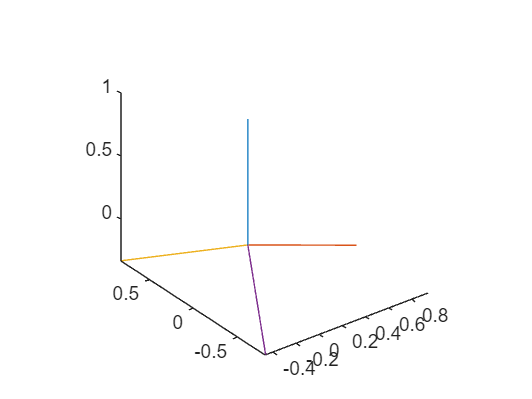

%% 构象坐标转换
m4_sphe_arr=table2array(readtable("M4.csv"));
m4_rect_arr=arr_sphe2rect(m4_sphe_arr);

figure;
for j=1:4
    plot3([m4_rect_arr(j,2) 0],[m4_rect_arr(j,3) 0],[m4_rect_arr(j,4) 0]);
    hold on;
end
axis equal

alpha_tb=[0,0,10];
pre_xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_procut_arr,adj_list,mtype_all_arr)

pre_xyz_tb =          0         0         0
         0         0    1.5080
    1.4215         0    2.0114
    1.0303         0   -0.3649
   -0.5152    0.8923   -0.3649
   -0.5152   -0.8923   -0.3649
   -0.5152   -0.8923    1.8729
   -0.5152    0.8923    1.8729
    2.1041   -0.1789    1.1767
    1.5444   -0.7893    2.7575


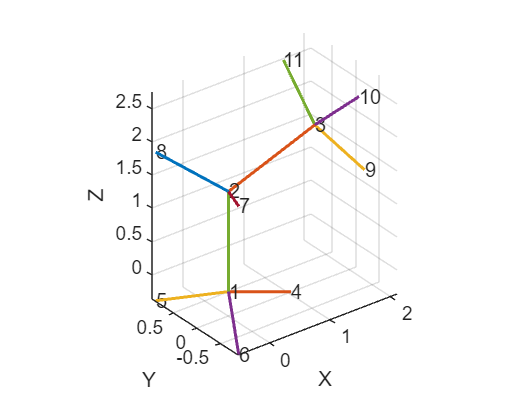

figure;
moledraw(pre_xyz_tb,adj_list)


[pre_sumE,sumEB,sumEA,sumEBA,sumEOOP,sumET,sumEVDW]=getE(pre_xyz_tb,nhc,bs_procut_arr,ab_procut_arr,sb_fastcut_arr,sb_cmplcut_arr,opb_fastcut_arr,opb_cmplcut_arr,ti_fastcut_arr,ti_cmplcut_arr,vdw_tb,big_adj_list,mtype_all_arr)

pre_sumE = 3.0609

sumEB = 0

sumEA = 5.6726e-05

sumEBA = 0

sumEOOP = 0

sumET = -13.0581

sumEVDW = 16.1189

% % 参数设置
% %maxmin_arr=table2array(max_xyz);
% alpha_min = 0;  % 请替换为实际的最小值
% alpha_max = 360; % 请替换为实际的最大值
% 
% % 将初始坐标矩阵转换为向量（fmincon需要向量输入）
% %x0 = pre_xyz_tb(:);  % 将n×3矩阵展平为3n×1向量
% 
% % 设置边界约束
% n = size(alpha_tb, 2);
% lb = alpha_min * ones(1,n);  % 下界向量
% ub = alpha_max * ones(1,n);  % 上界向量
% 
% % 增加随机性和多次重启策略
% num_runs = nhc;  % 进行5次独立优化尝试，每次使用不同的初始值
% best_fval = Inf;
% best_a_opt = [];
% 
% swarm_count=50
% tic;
% for run = 1:num_runs
%     % 每次运行时生成不同的初始粒子群
%     initial_swarm = alpha_min + (alpha_max - alpha_min) * rand(swarm_count, n);  % 随机生成初始粒子群
% 
%     % PSO参数设置
%     options = optimoptions('particleswarm', ...
%         'SwarmSize',swarm_count, ...               % 粒子群大小
%         'MaxIterations', nhc*2, ...           % 最大迭代次数
%         'Display', 'iter', ...              % 显示优化过程
%         'FunctionTolerance', 1e-6, ...      % 设置较小的目标函数容差
%         'InitialSwarmMatrix', initial_swarm, ...  % 初始粒子群矩阵
%         'OutputFcn', @psoOutputFunction);   % 输出函数
% 
%     % 目标函数包装器
% 
%     objective_function = @(alpha_tb) objective_wrapper(alpha_tb,ac,nhc_all_tb,bs_procut_arr,ab_procut_arr,sb_fastcut_arr,sb_cmplcut_arr,opb_fastcut_arr,opb_cmplcut_arr,ti_fastcut_arr,ti_cmplcut_arr,vdw_tb,adj_list,big_adj_list,mtype_all_arr);
% 
%     % 执行粒子群优化
%     fprintf('开始第 %d 次优化...\n', run);
% 
%     [opt_alpha_tb, fval] = particleswarm(objective_function, length(alpha_tb), lb, ub, options);
% 
% 
%     % 如果当前结果更好，则更新最优解
%     if fval < best_fval
%         best_fval = fval;
%         best_a_opt = opt_alpha_tb;
%     end
% 
%     % 显示每次优化的时间和目标函数值
%     fprintf('第 %d 次优化完成！\n', run);
%     fprintf('当前目标函数值: %f\n', fval);
% end
% 
% optimization_time = toc;
% % 显示最终优化结果
% fprintf('全局最优解已找到！\n');
% fprintf('优化完成，最优目标函数值: %f\n', best_fval);
% fprintf('最终优化时间: %.2f 秒\n', optimization_time);
% 
% 
% % 目标函数包装器
% function sumE = objective_wrapper(alpha_tb,ac,nhc_all_tb,bs_procut_arr,ab_procut_arr,sb_fastcut_arr,sb_cmplcut_arr,opb_fastcut_arr,opb_cmplcut_arr,ti_fastcut_arr,ti_cmplcut_arr,vdw_tb,adj_list,big_adj_list,mtype_all_arr);
% 
% mid_xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_procut_arr,adj_list,mtype_all_arr);
% nhc=size(nhc_all_tb,1);
% [sumE,~,~,~,~,~,~]=getE(mid_xyz_tb,nhc,bs_procut_arr,ab_procut_arr,sb_fastcut_arr,sb_cmplcut_arr,opb_fastcut_arr,opb_cmplcut_arr,ti_fastcut_arr,ti_cmplcut_arr,vdw_tb,big_adj_list,mtype_all_arr);
% 
% end
% % 自定义输出函数
% function stop = psoOutputFunction(~, optimValues, ~)
%     stop = false;
%     % 检查 optimValues 中的字段名，避免错误访问
%     if isfield(optimValues, 'Generation') && isfield(optimValues, 'BestFitness')
%         % 每20次迭代输出一次中间结果
%         if mod(optimValues.Generation, 20) == 0
%             fprintf('迭代次数: %d, 当前目标函数值: %.4f\n', ...
%                 optimValues.Generation, optimValues.BestFitness);
%         end
%     else
%         % 输出其他可用信息（如果字段名有所不同）
%         disp('当前optimValues中没有Generation或BestFitness字段');
%     end
% end
% opt_xyz_tb=xyzprecal(best_a_opt,ac,nhc_all_tb,bs_procut_arr,adj_list,mtype_all_arr);


% tic
% record_tb=zeros(90,2);
% min_jk=[0,0]
% min_E=100
% opt_xyz_tb=[];
% 
% acc=1e-4
% alpha_tb=[10,0,0];
% for i=1:size(alpha_tb)
%     oldE=0
%     newE=Inf
%     now_range=[0,360];
%     while(abs(newE-oldE)<1e-4)
%         oldE=newE;
%         alpha_tb(1,i)=sum(now_range)/2
%         pre_xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_procut_arr,adj_list,mtype_all_arr);
%         [newE,~,~,~,~,~,~]=getE(pre_xyz_tb,nhc,bs_procut_arr,ab_procut_arr,sb_fastcut_arr,sb_cmplcut_arr,opb_fastcut_arr,opb_cmplcut_arr,ti_fastcut_arr,ti_cmplcut_arr,vdw_tb,big_adj_list,mtype_all_arr);
% 
%         if min_E>sumE
%             min_E=sumE;
%             opt_xyz_tb=pre_xyz_tb;
%         end
%         %record_tb(k,:)=[k,sumE];
%         % if mod(k,20)==0
%         %     disp(k)
%         % end
%     end
% 
% end
% 
% elapsedTime = toc;
% disp(['运行时间: ', num2str(elapsedTime),'s']);


record_tb=zeros(90,2);
min_jk=[0,0];
min_E=Inf;
%opt_xyz_tb=[];

tic
for j=50
    for k=1:360
        alpha_tb=[10,j,k];
        pre_xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_procut_arr,adj_list,mtype_all_arr);
        [sumE,~,~,~,~,~,~]=getE(pre_xyz_tb,nhc,bs_procut_arr,ab_procut_arr,sb_fastcut_arr,sb_cmplcut_arr,opb_fastcut_arr,opb_cmplcut_arr,ti_fastcut_arr,ti_cmplcut_arr,vdw_tb,big_adj_list,mtype_all_arr);

        if min_E>sumE
            min_jk=[j,k];
            min_E=sumE;
            % opt_xyz_tb=pre_xyz_tb;
        end
        record_tb(k,:)=[k,sumE];
        % if mod(k,60)==0
        %     disp(k)
        % end
    end

end
elapsedTime = toc;
disp(['运行时间: ', num2str(elapsedTime),'s']);

运行时间: 4.3777s


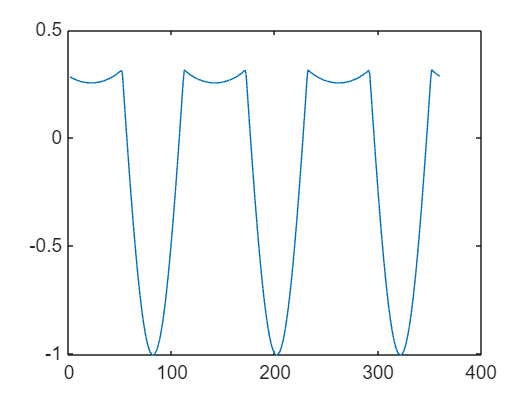

opt_xyz_tb=xyzprecal([10,min_jk],ac,nhc_all_tb,bs_procut_arr,adj_list,mtype_all_arr);
figure;
plot(record_tb(:,1),record_tb(:,2),"-")

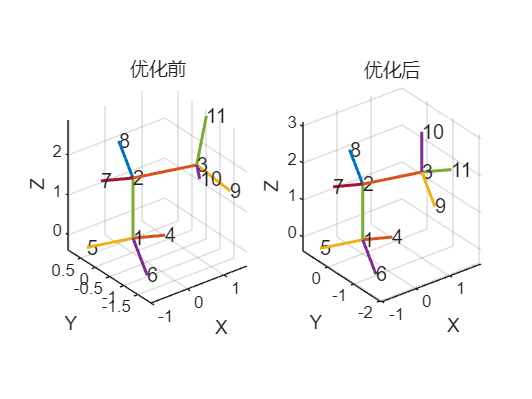


figure;
subplot(1,2,1)
moledraw(pre_xyz_tb,adj_list)
title("优化前")

subplot(1,2,2)
moledraw(opt_xyz_tb,adj_list)
title("优化后")


[sumE,sumEB,sumEA,sumEBA,sumEOOP,sumET,sumEVDW]=getE(opt_xyz_tb,nhc,bs_procut_arr,ab_procut_arr,sb_fastcut_arr,sb_cmplcut_arr,opb_fastcut_arr,opb_cmplcut_arr,ti_fastcut_arr,ti_cmplcut_arr,vdw_tb,big_adj_list,mtype_all_arr)

sumE = -1.0052

sumEB = 0

sumEA = 5.6726e-05

sumEBA = 0

sumEOOP = 0

sumET = -13.1458

sumEVDW = 12.1405

% pre_xyz_tb
% opt_xyz_tb

function tb=readcsv(csv_filename)
csv_folder = "../Values/MMFF94_CSV";
tb = readtable(fullfile(csv_folder,csv_filename));
end

function rect=sphe2rect(r,theta,varphi)
x=r*sind(varphi)*cosd(theta);
y=r*sind(varphi)*sind(theta);
z=r*cosd(varphi);
rect=[x,y,z];
end

% function r0=r0find(r0_tb,mtype_tb,seq_i,seq_j)
% mtype_i=mtype_tb(seq_i+1,1);
% mtype_j=mtype_tb(seq_j+1,1);
% row=matchmtype("R0",r0_tb,[mtype_i,mtype_j],["MTYPE_I","MTYPE_J"],"No");
% r0=row{1,"R0"};
% end


function [vec_ox,vec_oy,vec_oz]=gencoosys(xyz_tb,now_parent,now_child)
% 求解oz
vec_oz=xyz_tb(now_child+1,:)-xyz_tb(now_parent+1,:);
vec_oz=vec_oz/norm(vec_oz);

%求解ox
%vec_ox=genvec_xyz(zeros(1,3));
vec_ox=zeros(1,3);
if sum(vec_oz(1,2:3))==0
vec_ox(1,1)=0;
vec_ox(1,2)=1;
else
vec_ox(1,1)=1;
vec_ox(1,2)=0;
end
c_xz=dot(vec_ox,vec_oz);
if c_xz~=0
    vec_ox(1,3)=-c_xz/vec_oz(1,3);
end
vec_ox=vec_ox/norm(vec_ox);
%% 求解oy
vec_oy=cross(vec_oz,vec_ox);
vec_oy=vec_oy/norm(vec_oy);
end



function [Rv_ij,epsilon_ij]=precalEVDWParam(vdw_tb,mtype_arr)
mi=mtype_arr(1,1);
mj=mtype_arr(1,2);
A_i=vdw_tb{mi,"A_I"};
A_j=vdw_tb{mj,"A_I"};
G_i=vdw_tb{mi,"G_I"};
G_j=vdw_tb{mj,"G_I"};
N_i=vdw_tb{mi,"N_I"};
N_j=vdw_tb{mj,"N_I"};
alpha_i=vdw_tb{mi,"ALPHA_I"};
alpha_j=vdw_tb{mj,"ALPHA_I"};
B=0.2;
beta=12;
Rv_ii=A_i*alpha_i^0.25;
Rv_jj=A_j*alpha_j^0.25;
gamma_ij=(Rv_ii-Rv_jj)/(Rv_ii+Rv_jj);
Rv_ij=0.5*(Rv_ii+Rv_jj)*(1+B*(1-exp(-beta*gamma_ij^2)));
epsilon_ij=181.16*G_i*G_j*alpha_i*alpha_j/((alpha_i/N_i)^0.5+(alpha_j/N_j)^0.5)/Rv_ij^6;
end



% function row=matchmtype(des_ch,tb,mtype_arr,mtype_ch,is_jl_solid)
% dsize=size(des_ch,2);
% row=array2table(zeros(1,dsize),"VariableNames",des_ch);
% 
% for i=1:size(tb,1)
%     rm=tb{i,mtype_ch};
%     judge=false;
%     if is_jl_solid~="Yes"
%         rm_f=fliplr(rm);
%         judge=isequal(rm,mtype_arr) || isequal(rm_f,mtype_arr);
%     else
%         if mtype_arr(1,2)==rm(1,2)&& mtype_arr(1,4)==rm(1,4)
%             judge=mtype_arr(1,1)==rm(1,1)||mtype_arr(1,3)==rm(1,3);
%         end
%     end
%     if judge
%         for j=1:size(des_ch,2)
%             row{1,des_ch(1,j)}=tb{i,des_ch(1,j)};
%         end
%         break
%     end
% end
% end


function m_rect_arr=arr_sphe2rect(m_sphe_arr)
m_rect_arr=zeros(size(m_sphe_arr));
for i=1:size(m_sphe_arr,1)
    rect=sphe2rect(m_sphe_arr(i,2),m_sphe_arr(i,3),m_sphe_arr(i,4));
    m_rect_arr(i,:)=[m_sphe_arr(i,1),rect];
end
% m4_name=["Seq","X","Y","Z"];
% m_rect_tb=array2table(m4_rect,"VariableNames",m4_name);
end

function r=xyz2r(xyz_ij)
r=sqrt(sum((xyz_ij(1,:)-xyz_ij(2,:)).^2));
end

function vartheta=xyz2vartheta(xyz_ijk)
a=xyz_ijk(1,:)-xyz_ijk(2,:);
b=xyz_ijk(3,:)-xyz_ijk(2,:);
vartheta=acosd(dot(a,b)/(norm(a)*norm(b)));
end

function phi=xyz2phi(xyz_ijkl)
a=xyz_ijkl(1,:)-xyz_ijkl(2,:);
b=xyz_ijkl(3,:)-xyz_ijkl(2,:);
c=xyz_ijkl(4,:)-xyz_ijkl(3,:);

n_ab=cross(a,b);
n_bc=cross(b,c);

phi_1=acosd(dot(n_ab,n_bc)/norm(n_ab)/norm(n_bc));
k=-dot(a,b)/dot(b,b);
d=a+k*b;
judge=dot(d,c)<0;
if judge
    phi=180-phi_1;
else
    phi=phi_1;
end
end

function chi=xyz2chi(xyz_ijkl)
a=xyz_ijkl(1,:)-xyz_ijkl(2,:);
b=xyz_ijkl(3,:)-xyz_ijkl(2,:);
c=xyz_ijkl(4,:)-xyz_ijkl(2,:);
n=cross(a,b);
chi=abs(90-acosd(dot(c,n)/norm(c)/norm(n)));
end

function rec_node=bfs_finddepth(adj_list,start_pos,depth)
adj_key={num2str(start_pos)};
if depth==0 || ~isKey(adj_list,adj_key)
    rec_node= start_pos;
    return
else
    now_node_arr=adj_list(adj_key);
    now_node_arr=now_node_arr{:};
    rec_node=start_pos;
    for i=1:size(now_node_arr,2)
        rec_node=[rec_node, bfs_finddepth(adj_list,now_node_arr(1,i),depth-1)];
    end
end
end

%% 初始三维坐标生成
function xyz_tb=xyzprecal(alpha_tb,ac,nhc_all_tb,bs_pro_arr,adj_list,mtype_all_arr)

%% 待修改部分
m4_sphe_arr=table2array(readtable("M4.csv"));

nhc=size(nhc_all_tb,1);
xyz_tb=zeros(ac,3);

rec_xyz=[1 zeros(1,ac-1)];

for j=1:nhc
    now_parent=j-1;
    m=nhc_all_tb(j,1);
    if m~=4
        disp(m)
        continue
    end
    nb_node=adj_list({num2str(now_parent)});
    nb_node=nb_node{:};
    nsize=size(nb_node,2);

    new_m4_arr=m4_sphe_arr;
    new_m4_arr(:,3)=mod(m4_sphe_arr(:,3)+alpha_tb(1,j),360);
    m4_rect_arr=arr_sphe2rect(new_m4_arr);
    B=[];
    for i=1:nsize
        now_child=nb_node(1,i);
        index_ij=[now_child,now_parent]+1;
        mtype_ij=mtype_all_arr(index_ij,1)';
        r0=bs_pro_arr(mtype_ij(1,1),mtype_ij(1,2),1);
        if i==1
            %% 第二个原子
            if j==1
                xyz_tb(now_child+1,:)=[0,0,r0];
                rec_xyz(1,now_child+1)=1;
            end
            %% 确定坐标系II基矢ox,oy,oz
            [vec_ox,vec_oy,vec_oz]=gencoosys(xyz_tb,now_parent,now_child);

            B=[vec_ox; vec_oy; vec_oz];
        elseif now_child>now_parent &&rec_xyz(1,now_child+1)==0
            %% 向量旋转公式
            adot=m4_rect_arr(i,2:end)*B;
            xyz_i=(r0*adot)+xyz_tb(now_parent+1,:);
            xyz_tb(now_child+1,:)=xyz_i;
            rec_xyz(1,now_child+1)=1;
        end
    end

end

end

function moledraw(xyz_tb,adj_list)
nhc=size(keys(adj_list),1);
for j=1:nhc
    nb_node=adj_list({num2str(j-1)});
    nb_node=sort(nb_node{:});
    nsize=size(nb_node,2);
    for i=1:nsize
        line_parent_child(xyz_tb,j,nb_node(1,i)+1);
        hold on;
    end
end
for i=1:size(xyz_tb,1)
    text(xyz_tb(i,1),xyz_tb(i,2),xyz_tb(i,3),num2str(i));
end
axis equal
grid on
box off
xlabel("X")
ylabel("Y")
zlabel("Z")

end


function [sumE,sumEB,sumEA,sumEBA,sumEOOP,sumET,sumEVDW]=getE(xyz_tb,nhc,bs_pro_arr,ab_pro_arr,sb_fast_arr,sb_cmpl_arr,opb_fast_arr,opb_cmpl_arr,ti_fast_arr,ti_cmpl_arr,vdw_tb,big_adj_list,mtype_all_arr)



ac=size(xyz_tb,1);

max_m=6;
r_ij_tb=zeros(ac,ac);
dr_ij_tb=zeros(size(r_ij_tb));

var_ijk_tb=zeros(nhc,max_m,max_m);
var_ijk_tb(var_ijk_tb==0)=NaN;
dvar_ijk_tb_rad=var_ijk_tb;

mtype_short = sort(unique(mtype_all_arr, 'rows', 'stable'),1);
max_mtype_count=size(mtype_short,1);
max_mtype=max(mtype_short,[],"all");
mtype_2_mid=zeros(max_mtype,1);
for i=1:max_mtype_count
    mt=mtype_short(i,1);
    mtype_2_mid(mt,1)=i;
end

Rv_ij_mid_tb=zeros(max_mtype_count,max_mtype_count);
epsilon_ij_mid_tb=zeros(max_mtype_count,max_mtype_count);

Rv_ij_tb=zeros(ac,ac);
epsilon_ij_tb=zeros(ac,ac);


%% 总势能计算
sumEB=0;
sumEA=0;
sumEBA=0;
sumEOOP=0;
sumET=0;
sumEVDW=0;

% Rv_ij表坐标变换
for i=1:max_mtype_count
    for j=1:max_mtype_count
        [Rv_ij_mid_tb(i,j),epsilon_ij_mid_tb(i,j)]=precalEVDWParam(vdw_tb,mtype_all_arr(mtype_short([i,j],1),1)');
        Rv_ij_mid_tb(j,i)=Rv_ij_mid_tb(i,j);
        epsilon_ij_mid_tb(j,i)=epsilon_ij_mid_tb(i,j);
    end
end

for j=1:nhc
    now_parent_j=j-1;
    nb_node=big_adj_list({num2str(now_parent_j)});
    nb_node=sort(nb_node{:});
    nsize=size(nb_node,2);
    for i=1:nsize
        for k=(i+1):nsize
            now_child_i=nb_node(1,i);
            now_child_k=nb_node(1,k);
            index_ijk=[now_child_i,now_parent_j,now_child_k]+1;

            xyz_ijk=xyz_tb(index_ijk,:);
            var_ijk_tb(j,i,k)=xyz2vartheta(xyz_ijk);

            mtype_ijk=mtype_all_arr(index_ijk,1)';
            dvar_ijk_tb_rad(j,i,k)=deg2rad(var_ijk_tb(j,i,k)-ab_pro_arr(mtype_ijk(1,1),mtype_ijk(1,2),mtype_ijk(1,3),1));
            dvar_ijk_tb_rad(j,k,i)=dvar_ijk_tb_rad(j,i,k);
        end
    end
end

for j=1:ac
    for i=j:ac

        index_ij=[i,j];
        mtype_ij=mtype_all_arr(index_ij,1)';
        new_id=mtype_2_mid(mtype_ij,1)';
        Rv_ij_tb(i,j)=Rv_ij_mid_tb(new_id(1,1),new_id(1,2));
        Rv_ij_tb(j,i)=Rv_ij_tb(i,j);
        epsilon_ij_tb(i,j)=epsilon_ij_mid_tb(new_id(1,1),new_id(1,2));
        epsilon_ij_tb(j,i)=epsilon_ij_tb(i,j);
        if i~=j
            xyz_ij=xyz_tb([i j],:);
            r_ij_tb(i,j)=xyz2r(xyz_ij);
            r_ij_tb(j,i)=r_ij_tb(i,j);
            dr_ij_tb(i,j)=r_ij_tb(i,j)-bs_pro_arr(mtype_ij(1,1),mtype_ij(1,2));
            dr_ij_tb(i,j)=dr_ij_tb(j,i);
        end
    end
end

%% 计算各个能量
for j=1:nhc
    now_parent_j=j-1;
    nb_node=big_adj_list({num2str(now_parent_j)});
    nb_node=nb_node{:};
    nsize=size(nb_node,2);

    %% EB：对第i个原子只遍历编号比i大的相邻节点
    for i=1:nsize
        now_child=nb_node(1,i);
        if now_child>now_parent_j
            index_ij=[now_child,now_parent_j]+1;
            mtype_ij=mtype_all_arr(index_ij,1)';
            mi=mtype_ij(1,1);
            mj=mtype_ij(1,2);
            sumEB=sumEB+newgetEB(dr_ij_tb(i,j),bs_pro_arr(mi,mj,2));
        end
    end

    %% EA：遍历中心原子
    %% EBA：同EA
    for i=1:nsize
        for k=(i+1):nsize
            ci=nb_node(1,i)+1;
            cj=now_parent_j+1;
            ck=nb_node(1,k)+1;

            mtype_ijk=mtype_all_arr([ci,cj,ck],1)';

            mi=mtype_ijk(1,1);
            mj=mtype_ijk(1,2);
            mk=mtype_ijk(1,3);

            ti=sb_cmpl_arr(1,mi);
            tj=sb_cmpl_arr(2,mj);
            tk=sb_cmpl_arr(3,mk);

            sumEA=sumEA+newgetEA(dvar_ijk_tb_rad(j,i,k),ab_pro_arr(mi,mj,mk,2));
            sumEBA=sumEBA+newgetEBA(dr_ij_tb(j,i),dr_ij_tb(j,k),dvar_ijk_tb_rad(j,i,k),sb_fast_arr(ti,tj,tk,1),sb_fast_arr(ti,tj,tk,2));
            % sumEBA=sumEBA+newgetEBA(dr_ij,dr_kj,dvar,kba_ijk,kba_kji);
        end
    end
    %% EOOP：仅AllBond=3时
    if nsize==3
        for l=1:nsize
            now_child_l=nb_node(1,l);
            now_node_arr=nb_node;
            now_node_arr(1,l)=[];
            now_child_i=now_node_arr(1,1);
            now_child_k=now_node_arr(1,2);

            index_ijkl=[now_child_i,now_parent_j,now_child_k,now_child_l]+1;
            xyz_ijkl=xyz_tb(index_ijkl,:);
            chi_ijkl=deg2rad(xyz2chi(xyz_ijkl));
            mtype_ijkl=mtype_all_arr(index_ijkl,1)';

            ti=opb_cmpl_arr(1,mtype_ijkl(1,1));
            tj=opb_cmpl_arr(2,mtype_ijkl(1,2));
            tk=opb_cmpl_arr(2,mtype_ijkl(1,3));
            tl=opb_cmpl_arr(2,mtype_ijkl(1,4));

            sumEOOP=sumEOOP+newgetEOOP(chi_ijkl,opb_fast_arr(ti,tj,tk,tl,1));
        end
    end

    %% ET：同EB
    for k =j:nsize
        now_parent_k=nb_node(1,k);
        if now_parent_k<nhc
            node_i_arr=sort(cell2mat(big_adj_list({num2str(now_parent_j)})));
            node_l_arr=sort(cell2mat(big_adj_list({num2str(now_parent_k)})));
            insize=size(node_i_arr,2);
            lnsize=size(node_l_arr,2);
            for i=1:insize
                for l=1:lnsize
                    now_child_i=node_i_arr(1,i);
                    now_child_l=node_l_arr(1,l);
                    if now_child_l~=now_parent_j&&now_parent_k~=now_child_i
                        index_ijkl=[now_child_i,now_parent_j,now_parent_k,now_child_l]+1;
                        xyz_ijkl=xyz_tb(index_ijkl,:);
                        mtype_ijkl=mtype_all_arr(index_ijkl,1)';

                        ti=ti_cmpl_arr(1,mtype_ijkl(1,1));
                        tj=ti_cmpl_arr(2,mtype_ijkl(1,2));
                        tk=ti_cmpl_arr(3,mtype_ijkl(1,3));
                        tl=ti_cmpl_arr(4,mtype_ijkl(1,4));

                        phi=xyz2phi(xyz_ijkl);
                        %ET=newgetET(phi,V1,V2,V3)
                        sumET=sumET+newgetET(phi,ti_fast_arr(ti,tj,tk,tl,1),ti_fast_arr(ti,tj,tk,tl,2),ti_fast_arr(ti,tj,tk,tl,3));
                    end
                end
            end
        end
    end
end
for j=1:ac
    %% EVDW：BFS
    rec_node=bfs_finddepth(big_adj_list,j-1,2);
    rec_node_arr=zeros(1,ac);
    rnsize=size(rec_node,2);
    for ii=1:rnsize
        rec_node_arr(1,1+rec_node(1,ii))=true;
    end
    for bi=j:ac
        if rec_node_arr(1,bi)
            continue
        end
        index_ij=[j,bi];
        %mtype_ij=mtype_all_arr(index_ij,1)';
        R_ij=r_ij_tb(index_ij(1,1),index_ij(1,2));
        EVDW=newgetEVDW(R_ij,Rv_ij_tb(index_ij(1,1),index_ij(1,2)),epsilon_ij_tb(index_ij(1,1),index_ij(1,2)));
        sumEVDW=sumEVDW+EVDW;
    end
end
sumE=sumEB+sumEA+sumEBA+sumEOOP+sumET+sumEVDW;
end

function p=line_parent_child(xyz_tb,parent,child)
p=plot3([xyz_tb(child,1),xyz_tb(parent,1)], ...
    [xyz_tb(child,2),xyz_tb(parent,2)], ...
    [xyz_tb(child,3),xyz_tb(parent,3)],"-",LineWidth=1.5);
end


function EB=newgetEB(dr_ij,kb)
cs=-2;
EB=143.9525*kb/2*dr_ij^2*(1+cs*dr_ij+7/12*cs^2*dr_ij^2);
end

function EA=newgetEA(dvar,ka)
cb=-0.000122;
EA=0.043844*ka/2*dvar^2*(1+cb*dvar);
end


function EBA=newgetEBA(dr_ij,dr_kj,dvar,kba_ijk,kba_kji)
EBA=2.51210*(kba_ijk*dr_ij+kba_kji*dr_kj)*dvar;
end

function EOOP=newgetEOOP(chi_ijkl,koop)
EOOP=0.034844*koop/2*chi_ijkl^2;
end


function ET=newgetET(phi,V1,V2,V3)
ET=0.5*(V1*(1+cosd(phi))+V2*(1-cosd(2*phi)+V3*(1+cosd(3*phi))));
end

function EVDW=newgetEVDW(R_ij,Rv_ij,epsilon_ij)
EVDW=epsilon_ij*(1.07*Rv_ij/(R_ij+0.07*Rv_ij))^7*(1.12*Rv_ij^7/(R_ij+0.12*Rv_ij^7)-2);
end